# Actividad 1:

## Reconstrucción de señales muestreadas

### Reconstrucción no causal usando la función Sinc

clc
clear

Ts guarda los periodos de muestreo que se utilizarán durante la actividad

Ts=[0.51 0.5 0.49 0.1];

Se corre la simulación y toman de los .toworkspace las variables correspondientes

out = sim('actividad1simulink');

Ym1=out.simout1; 
t=out.tout;
Ym={out.simout2;
    out.simout3;
    out.simout4;
    out.simout5};

Se hace una estructura Yr que va a guardar todas las reconstrucciones, una reconstrucción de cada fila.

de esta forma se generan automáticamente todos los gráficos necesarios utilizando for, y aún así manteniendo guardados los vectores para posible futuro uso.

Yr={};
for i=[1:4]
    Yr=vertcat(Yr,reconstruccion(Ts(i),t,Ym{i}.data));
    subplot(2,2,i)
    
subplot(2,2,1)
xlim([0 70])
ylim([0.05 1.12])
subplot(2,2,2)
xlim([1.4 12.2])
ylim([-0.0124 0.0060])
subplot(2,2,3)
xlim([34 103])
ylim([-2.4 3.7])
subplot(2,2,4)
xlim([1.54 3.45])
ylim([0.929 1.026])
    titulo='Tiempo de muestreo: ' + string(Ts(i));
    hold on
    title(titulo)
    plot(Ym1.time,Ym1.data)
    stem(Ym{i}.time,Ym{i}.data)
    plot(t,Yr{i})
    hold off
    legend('Y', 'Ym', 'Yr')
end

### Reconstrucción causal usando retentores de orden 0.

clc
clear

Se corre la simulación y toman de los .toworkspace las variables correspondientes

out = sim('actividad1_2simulink');
Ts=[0.75 0.5 0.2 0.1 0.05 0.01];
Yreal=out.simout;
Ym={out.simout1;
    out.simout2;
    out.simout3;
    out.simout4;
    out.simout5;
    out.simout6}; 
t=out.tout;

se hacen todos los gráficos correspondientes mostrando las señales de workspace y reconstruidas usando un retentor de orden 0.

for i=[1:6]
    titulo='Tiempo de muestreo: ' + string(Ts(i)) + '[s]';
    subplot(2,3,i)
    hold on
    title(titulo)
    plot(Yreal)
    stairs(Ym{i}.time,Ym{i}.data)
    hold off
end


### Reconstrucción causal usando retentores de orden 1.

clc
clear

Se corre la simulación y toman de los .toworkspace las variables correspondientes

out = sim('actividad1_22simulink');
Ts=[0.75 0.5 0.2 0.1 0.05 0.01];
Yreal=out.simout;
Ym={out.simout1;
    out.simout2;
    out.simout3;
    out.simout4;
    out.simout5;
    out.simout6}; 
t=out.tout;

se hacen todos los gráficos correspondientes mostrando las señales de workspace y reconstruidas usando un retentor de orden 1.

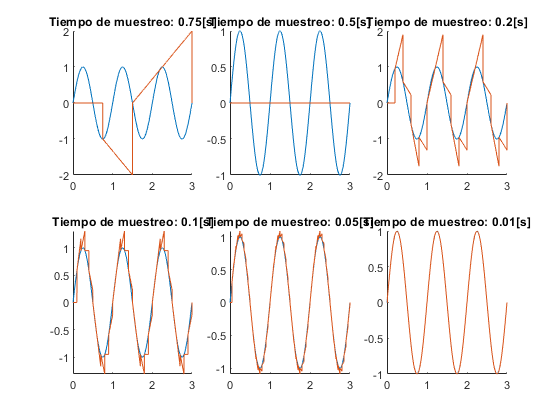

for i=[1:6]
    titulo='Tiempo de muestreo: ' + string(Ts(i)) + '[s]';
    subplot(2,3,i)
    hold on
    title(titulo)
    plot(Yreal)
    plot(Ym{i}.time,Ym{i}.data)
    
    hold off
end